%Cooling Curve Approximizations - Project 2
%Benjamin Oakes - Engineering Computer Applications

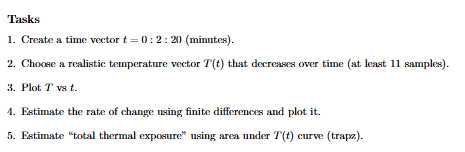


clear; % Clears all variables from the current workspace to prevent data conflicts
clc;   % Clears the Command Window for a clean output display


T_env = 22;      % Ambient (room) temperature in degrees Celsius
T0 = 90;         % Initial temperature of the object in Celsius
k = 0.045;       % Cooling constant (1/min)
time_limit = 60; % Total duration of the simulation in minutes

% Generates a row vector from 0 to time_limit with an interval of 1 minute
t = 0:1:time_limit; 

% Newton's Law of Cooling: T(t) = T_env + (T0 - T_env) * e^(-kt)
% Calculates the temperature at every point in the time vector 't'
T = T_env + (T0 - T_env) * exp(-k * t);

% Determine the status of the temperature for each time step
% Create a cell array to store string labels
status = cell(length(T), 1); 
for i = 1:length(T)
    if T(i) > 60
        status{i} = 'Hot';
    elseif T(i) > 35
        status{i} = 'Warm';
    else
        status{i} = 'Room Temp';
    end
end

% Combine the data into a table
CoolingTable = table(t', T', status, 'VariableNames', {'Time_min', 'Temp_Celsius', 'Status'});

% Display the first 15 rows of the table in the Command Window
disp('--- Cooling Curve Data Table (Partial) ---');

--- Cooling Curve Data Table (Partial) ---


disp(CoolingTable(1:15, :));

    Time_min    Temp_Celsius     Status 
    ________    ____________    ________

        0              90       {'Hot' }
        1          87.008       {'Hot' }
        2          84.147       {'Hot' }
        3          81.413       {'Hot' }
        4          78.798       {'Hot' }
        5          76.299       {'Hot' }
        6           73.91       {'Hot' }
        7          71.626       {'Hot' }
        8          69.442       {'Hot' }
        9          67.354       {'Hot' }
       10          65.359       {'Hot' }
       11          63.451       {'Hot' }
       12          61.627       {'Hot' }
       13          59.883       {'Warm'}
       14          58.216       {'Warm'}



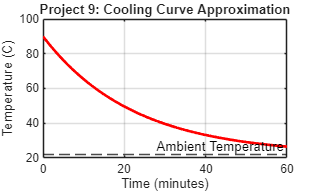


figure(1); % Creates figure window
plot(t, T, 'r-', 'LineWidth', 2); % Plots time vs temperature with a thick red line
grid on; % Adds a coordinate grid to the plot
xlabel('Time (minutes)'); % Labels the horizontal axis
ylabel('Temperature (C)'); % Labels the vertical axis
title('Project 9: Cooling Curve Approximation'); % Creates plot title

hold on; % Keeps the current plot so we can add more elements
yline(T_env, '--k', 'Ambient Temperature'); % Draws a black dashed line at T_env
hold off; % Releases the plot


% The intercept (t=0) represents the starting temperature (T0).
% The slope is non-linear; the rate of cooling is highest when the 
% temperature difference (T - T_env) is at its maximum.
fprintf('Initial Temperature: %.1f C\n', T(1));

Initial Temperature: 90.0 C


fprintf('Final Simulated Temperature: %.1f C\n', T(end));

Final Simulated Temperature: 26.6 C
